# **LAB SESSION 08**

## **-ve Binomial Distribution & Poission Distribution.**

**Objective:** To get familiar with -ve Binomial Distribution & Poission Destribution and their implementation in MATLAB

**Introduction:**

    **Negative Binomial Distribution:**

    It is a discrete probability distribution that models the # of failures in a sequence of independent and identically distributed Bernoulli Trials before a specified (non-random)  # of Successes **x **occurs.


$$p\left(X=x\right)=\overset{n-1}{\underset{x-1}{C}} p^x {\left(1-p\right)}^{n-x}$$


    **Poission Distribution:**

    A random varialbe is said to have Poission Destribution if a $\lambda$ (# of hits per unit time) is given and will have a probability density function (PDF):


$$P\left(x\right)=\frac{e^{-\lambda } \lambda^x }{x!}$$


%% Poission Distribution
clear all
clc

L = input('Enter Lamda \nL= '); %Population Size
t = input('Enter Time Interval \nt= ');
x = input('Enter # of Success:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n x =');
XL = length(x);

for j = 1:XL
    LT = L * t;
    P1 = (exp(-LT).*(LT.^x))./factorial(x);
    P = sum(P1);
end

    disp('Probability =')

Probability =


P

P = 4.8523e-08

**TASK # 1**

**A computer hard disk manufacturer has observed that flaws occur randomly in the manufacturing process at the average rate of two flaws in a 4 GB hard disk and has found this rate to be acceptable. What is the probability that a disk will be manufactured with no defects**

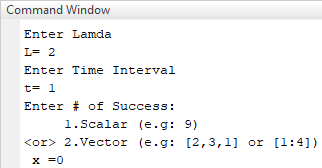

`Probability =`

`P = 0.1353`

**TASK # 2**

**The number of hits at a Web site in any time interval is a Poisson random variable. A particular site has on average λ = 2 hits per second. What is the probability that there are no hits in an interval of 0.25 seconds? What is the probability that there are no more than two hits in an interval of one second?**

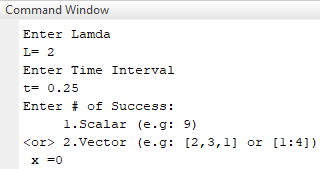

`Probability =`

`P = 0.6065`

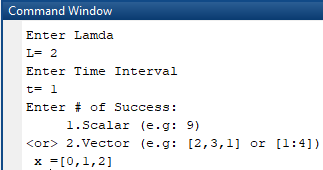

`Probability =`

`P = 0.6767`

**TASK # 3**

**Suppose a fast food restaurant can expect two customers every 3 minutes, on average. What is the probability that four or fewer patrons will enter the restaurant in a 9 minutes period?**

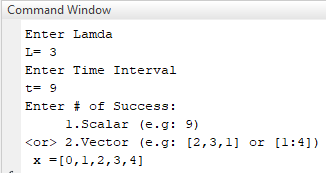

`Probability =`

`P = 4.8523e-08`

clear all
close all
clc

p = input('Enter probability of success "p"\n p =');
n = input('Enter # of Independent Trials "n"\n n =');
x = input('Enter # of Success:\n     1.Scalar (e.g: 9)\n<or> 2.Vector (e.g: [2,3,1] or [1:4])\n x =');

L = length(x);
for i = 1:L
    P = nchoosek(n-1,x-1).*(p.^x).*(1-p).^(n-x);
    F = sum(P);
end
    disp('Probability =')
F

**TASK # 1**

**A person conducting telephone surveys must get 3 more complete surveys before the job is finished. On each random dialed number 9% chances of reaching an adult who will complete the survey. What is the probability the 3 rd completed survey occurs on 10th call.**

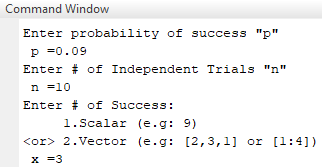

`Probability =`

`F = 0.0136`